# Практическое задание 2.

Приведём пример работы с изображением в приложении Matlab Image Viewer

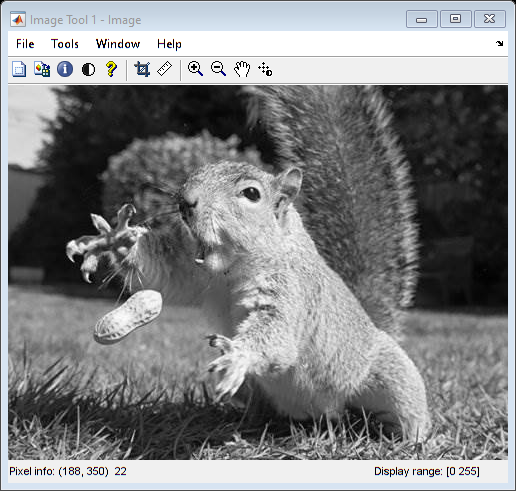

Image = rgb2gray(imread('Белка.jpg'));
imtool(Image);

Построим маску изображения Животного

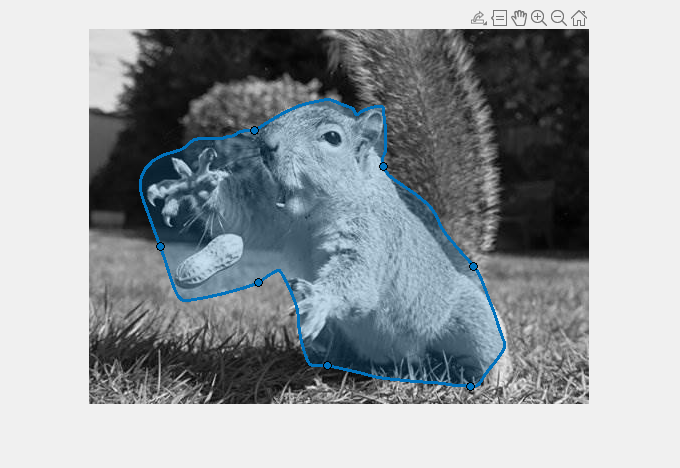

imshow(Image);
h = drawfreehand;

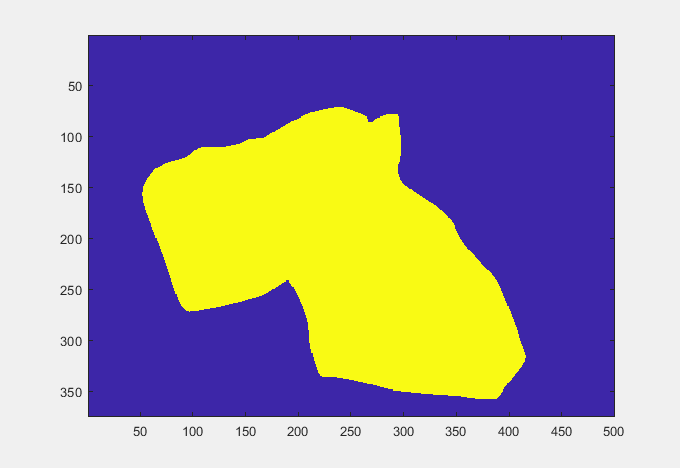

Mask = createMask(h);
imagesc(Mask);

Изучим возможности создания маски в программе ImageSegmenter.

Постройте маску используя разные способы (исключая способ ROI)

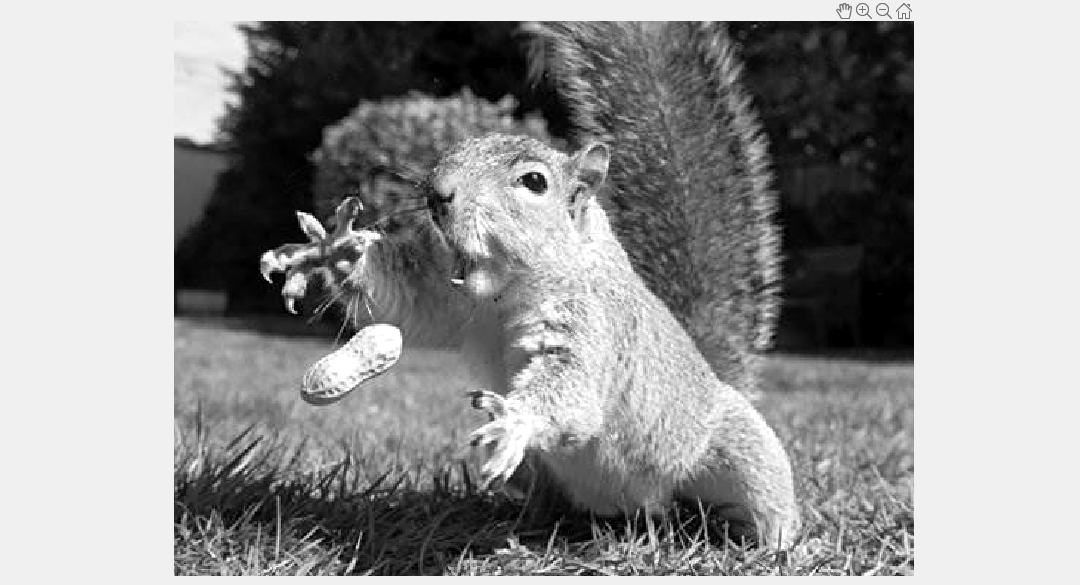

imageSegmenter(Image)

Составить и вывести Гистограммы и изображения с распределением экспонентциальным(степень 3) и Рэйлиха (степень 0.5)

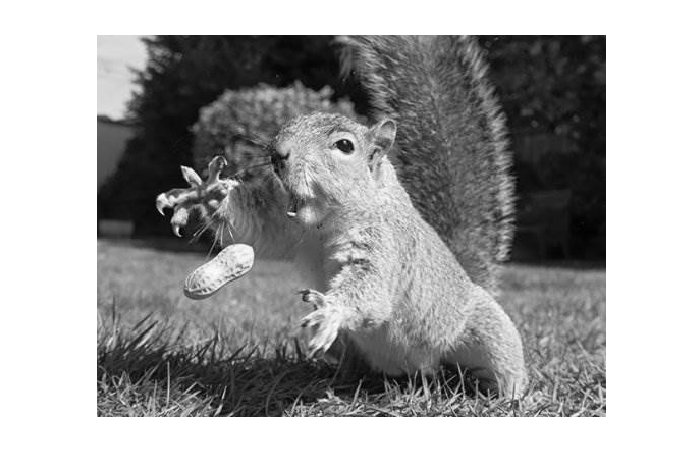

imshow(Image)

Гистограмма исходного изображения

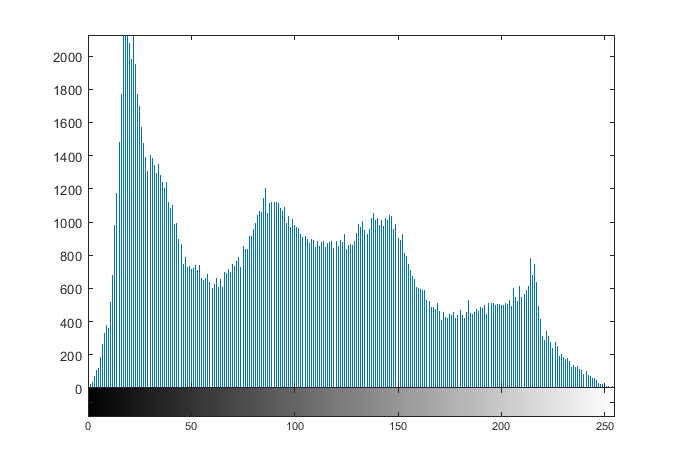

imhist(Image)

Выравнивание по яркости  изображения и его гистограмма. Смотри help histeq

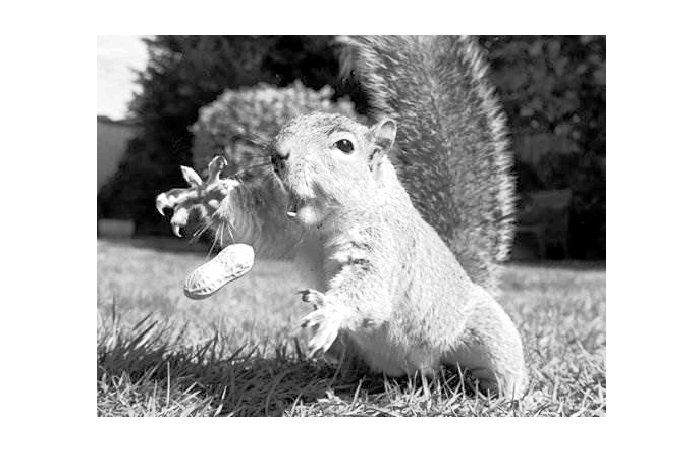

Image1 = histeq(Image);
imshow(Image1)

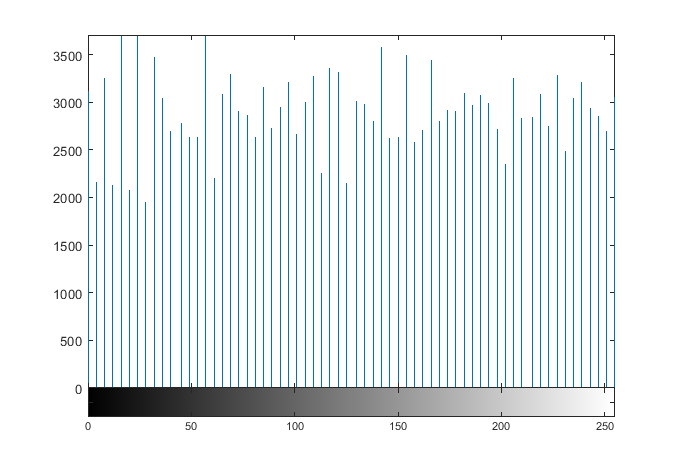

imhist(Image1)

Равномерное преобразование яркости.

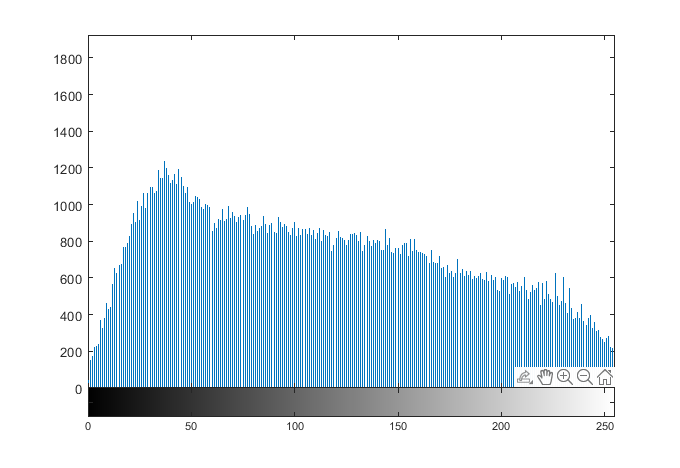

Image2 =adapthisteq(Image,"Distribution","exponential","Alpha",0.1);
imhist(Image2)

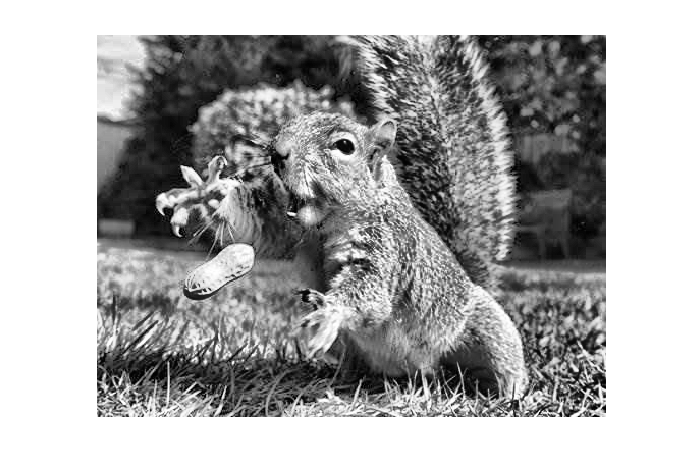

imshow(Image2)

Место для кода: